# Comparing the four EEPN compensation cases: TGN model vs. full-system simulation

This script generalizes Temporal_Gaussian_Noise_Model_EEPN_Matlab.m (which covers only carrier phase recovery, CPR) to the four receiver structures discussed in [2], classified by the order of frequency-dependent phase error (FDPE) they compensate:

- **No compensation (LO-PC)** -- removes only the instantaneous LO phase itself (order -).

- **CPR** -- compensates a constant phase offset a^(0) (order 0).

- **Timing recovery** -- additionally compensates a linear phase term a^(1)*f (order 1).

- **Adaptive filtering (higher-order compensation)** -- compensates a full degree-Ntilde polynomial, sum_n a^(n)*f^n (order Ntilde).

For each case, we compare the Temporal Gaussian Noise (TGN) model's predicted time-varying EEPN distortion power against a full-system simulation using the **ideal, genie-aided** ("phase_based") realization of that compensation order -- i.e. the compensation directly uses the true LO phase Rx_phi rather than a receiver-realistic (data-aided or blind) estimate of it. This isolates the TGN model's accuracy from estimator noise and gives a clean, consistent comparison across all four cases; see [2] for practical data-aided/blind estimators (not included here).

[1] B. Geiger, F. Buchali, V. Aref, and L. Schmalen, "A Temporal Gaussian Noise Model for Equalization-enhanced Phase Noise," Proc. ECOC, Copenhagen, Denmark, 2025.

[2] B. Geiger, F. Buchali, V. Aref, and L. Schmalen, "Modeling and Mitigation of Equalization-Enhanced Phase Noise," Proc. ECOC, 2026.

## Parameters (ECOC26 reference case)

addpath("functions\")

cfg.symbol_rate = 130e9;                % Symbol rate in Baud
cfg.linewidth = 115e3;                  % LO linewidth in Hertz
cfg.fiber_length = 2850;                % Fiber length in km

cfg.mod_order = 16;                     % Modulation format
cfg.oversampling_factor = 2;            % Oversampling factor

cfg.RRC_roll_off = 0.01;                % RRC roll-off factor (pulse shaping & matched filter)
cfg.RRC_span = 200;                     % RRC span (pulse shaping & matched filter)

cfg.snr = 1300;                         % Signal-to-noise ratio in dB (effectively noise-free, isolates EEPN)

% Kept moderate here for a fast sanity check (a few tens of seconds);
% raise this (e.g. to 1e6 or more) for CCDF tails deep enough to be
% paper-quality.
cfg.num_transmission_symbols = 2e5;

cfg.D_cd = 23e-12/(1e-9);               % Chromatic dispersion parameter in s/(km*m)

cfg.block_length_SNR_evaluation = 1000; % Number of symbols used to estimate the SNR after transmission

% Compensation filter settings, shared by timing_recovery and
% full_compensation (see private/apply_block_fdpe_filter.m).
cfg.compensation_order = 10;            % Polynomial order of the adaptive filter (Ntilde_AF in [2])
cfg.compensation_filter_taps = 60;
cfg.compensation_block_length = 1000;
cfg.compensation_block_overlap = 0.95;

% All four cases use the ideal, genie-aided ("phase_based") compensation
% as the reference simulation; see the header comment above.
rng(1);

cfg = init_parameter(cfg);
cfg.discard_symbols_analysis = 2*cfg.CD_memory;

## Transmitter, channel and receiver front end

Simulates the full pipeline once: Tx symbols -> pulse shaping -> CD channel + AWGN -> LO phase noise -> CD compensation -> matched filter -> downsampling. All four compensation cases below operate on the same Rx_symbols/Rx_phi realization.

[Rx_symbols, Tx_symbols, Rx_phi] = generate_received_symbols(cfg);

## Simulation: apply the four compensation cases (ideal, genie-aided reference)

Rx_symbols_LO_PC = LO_phase_cancellation(Rx_symbols, Rx_phi, cfg);
Rx_symbols_CPR = CPR(Rx_symbols, Rx_phi, cfg);
Rx_symbols_TR = timing_recovery(Rx_symbols, Rx_phi, cfg);
Rx_symbols_full = full_compensation(Rx_symbols, Rx_phi, cfg);

## Temporal Gaussian Noise model: instantaneous EEPN distortion power

Each case's model distortion power is computed the same way, via its own dedicated calculate_EEPN_distortion_power_* function, independently of the compensation functions above (even though timing_recovery and full_compensation internally use the exact same windowed-fit engine).

EEPN_power_model_LO_PC = calculate_EEPN_distortion_power_LO_phase_cancellation(Rx_phi, cfg);
EEPN_power_model_CPR = calculate_EEPN_distortion_power_CPR(Rx_phi, cfg);
EEPN_power_model_TR = calculate_EEPN_distortion_power_timing_recovery(Rx_phi, cfg);
EEPN_power_model_full = calculate_EEPN_distortion_power_full_compensation(Rx_phi, cfg);

## Evaluation: simulated error power (Sim) vs. model (system noise + EEPN power)

sigma_simulation_LO_PC = estimate_moving_error_power(Rx_symbols_LO_PC, Tx_symbols, cfg);
sigma_simulation_CPR   = estimate_moving_error_power(Rx_symbols_CPR,   Tx_symbols, cfg);
sigma_simulation_TR    = estimate_moving_error_power(Rx_symbols_TR,    Tx_symbols, cfg);
sigma_simulation_full  = estimate_moving_error_power(Rx_symbols_full,  Tx_symbols, cfg);

% Match estimate_moving_error_power.m's own trimming convention exactly
% (discard cfg.discard_symbols_analysis symbols at the start, one more
% than that at the end) so the model curves align with the Sim curves.
discard = @(x) x(cfg.discard_symbols_analysis+1 : end-cfg.discard_symbols_analysis-1);

sigma_model_LO_PC = cfg.system_noise_power + discard(EEPN_power_model_LO_PC);
sigma_model_CPR   = cfg.system_noise_power + discard(EEPN_power_model_CPR);
sigma_model_TR    = cfg.system_noise_power + discard(EEPN_power_model_TR);
sigma_model_full  = cfg.system_noise_power + discard(EEPN_power_model_full);

## Sanity check

Compensating more FDPE terms can only reduce the residual distortion power: mean(LO-PC) >= mean(CPR) >= mean(timing recovery) >= mean(full compensation).

mean_LO_PC = mean(sigma_model_LO_PC);
mean_CPR   = mean(sigma_model_CPR);
mean_TR    = mean(sigma_model_TR);
mean_full  = mean(sigma_model_full);

fprintf('Mean distortion+noise power: LO-PC=%.3e, CPR=%.3e, timing recovery=%.3e, full compensation=%.3e\n', ...
    mean_LO_PC, mean_CPR, mean_TR, mean_full);

Mean distortion+noise power: LO-PC=9.205e-03, CPR=5.701e-03, timing recovery=2.812e-03, full compensation=5.834e-04



assert(mean_LO_PC >= mean_CPR && mean_CPR >= mean_TR && mean_TR >= mean_full, ...
    'Expected mean(LO-PC) >= mean(CPR) >= mean(timing recovery) >= mean(full compensation).');

## Comparison: distortion + noise power over time

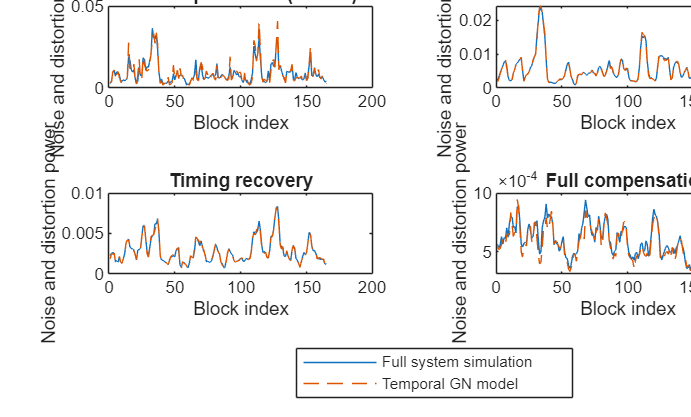

case_names = ["No compensation (LO-PC)", "CPR", "Timing recovery", "Full compensation"];
sigma_simulation_all = {sigma_simulation_LO_PC, sigma_simulation_CPR, sigma_simulation_TR, sigma_simulation_full};
sigma_model_all = {sigma_model_LO_PC, sigma_model_CPR, sigma_model_TR, sigma_model_full};

figure();
t_layout = tiledlayout(2, 2);
for idx = 1:4
    nexttile;
    h1 = plot(sigma_simulation_all{idx}(1:cfg.block_length_SNR_evaluation:end)); hold on;
    h2 = plot(sigma_model_all{idx}(1:cfg.block_length_SNR_evaluation:end), '--');
    title(case_names(idx));
    xlabel("Block index"); ylabel("Noise and distortion power");
end
lgd = legend([h1, h2], ["Full system simulation", "Temporal GN model"]);
lgd.Layout.Tile = 'south';
title(t_layout, "Distortion + noise power over time");

## Comparison: CCDF

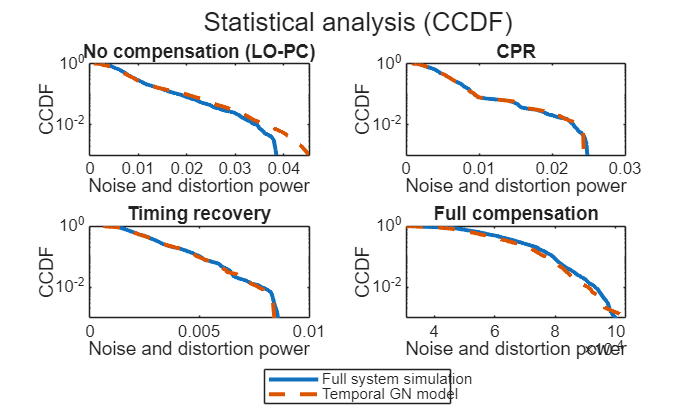

figure();
t_layout = tiledlayout(2, 2);
for idx = 1:4
    nexttile;
    [f_sim, t_sim] = ecdf(sigma_simulation_all{idx});
    [f_model, t_model] = ecdf(sigma_model_all{idx});
    h1 = semilogy(t_sim, 1-f_sim, "LineWidth", 2); hold on;
    h2 = semilogy(t_model, 1-f_model, "--", "LineWidth", 2);
    title(case_names(idx));
    xlabel("Noise and distortion power"); ylabel("CCDF"); ylim([1e-3 1]);
end
lgd = legend([h1, h2], ["Full system simulation", "Temporal GN model"]);
lgd.Layout.Tile = 'south';
title(t_layout, "Statistical analysis (CCDF)");

As in Temporal_Gaussian_Noise_Model_EEPN_Matlab.m, note that this idealized (genie-aided/phase_based) comparison differs from the full experimental results in [1],[2], which also include practical (data-aided/blind) DSP, dual-pol effects, etc.

Written by Benedikt Geiger.